# Transformada de Fourier Compleja

[⇦ Información general del análisis de Fourier](matlab: OpenOverview)

**Objetivos de aprendizaje**

- Recuerda la fórmula de Euler.

- Compara las series de Fourier complejas y reales.

- Visualiza la serie de Fourier compleja.

- Construye funciones utilizando la serie de Fourier compleja.

## Introducción

La serie de Fourier se puede definir utilizando senos y cosenos:


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


o un solo coseno parametrizado en términos de magnitud $A_n$ y fase $\phi_n$:


$$f(t) = \frac{A_0}{2} +  \sum_{n=1}^{\infty} A_n \cos\left( \frac{ n \pi } {L}  t - \phi_n \right)$$


Estas formas son intuitivamente simples pero pueden ser engorrosas de trabajar. En esta lección aprenderás sobre una tercera forma: *la serie de Fourier compleja*. Al utilizar números complejos, los dos conjuntos de parámetros se pueden combinar en un solo conjunto, lo que da una definición muy compacta. Más importante aún, al aprender sobre la serie de Fourier compleja, podrás comprender la transformada de Fourier, que siempre se define en términos de números complejos.

## La fórmula de Euler

Posiblemente la fórmula más sorprendente en matemáticas, la fórmula de Euler relaciona las exponenciales con las funciones trigonométricas utilizando números complejos:


$$e^{i \theta} = \cos \theta + i \sin \theta$$


Representada en el plano complejo, la fórmula de Euler traza un círculo.

   **Tarea.** Arrastra lentamente el control deslizante de abajo de 0 a 360 para trazar un círculo utilizando la fórmula de Euler.

thetad = 0; % En grados
complexCircle(thetad); % Función auxiliar que genera el gráfico

Al hacer que la entrada $\theta$ sea una función lineal del tiempo, la fórmula de Euler trazará un círculo con una velocidad que depende de la frecuencia angular $\omega$:


$$y(t) = e^{ i \omega t}$$


La frecuencia angular tiene unidades de rad/s. Graficar cada componente por separado con respecto al tiempo producirá dos gráficos: el componente real trazará una curva coseno, y el componente imaginario trazará una curva seno.

   **Tarea.** Establece la frecuencia de $y(t)$ en el control deslizante de abajo y luego ejecuta la sección para crear un gráfico animado de $e^{i\omega t}$ en el plano complejo junto con la serie temporal.

freq = 1; % frecuencia en Hz
 
omega = freq*2*pi; % frecuencia angular en rad/s
traceSineCosine(1,omega,0,1.2,true); % Función auxiliar que traza la curva

## Serie de Fourier compleja

Al cambiar la frecuencia angular $\omega$ de la función $e^{i\omega t}$, puedes crear funciones seno y coseno con diversas frecuencias, al igual que en una serie de Fourier estándar. Sin embargo, los senos y cosenos estarán contenidos en partes reales y complejas de la función:


$$e^{ i \omega t} = \cos ( \omega t ) + i \sin (\omega t)$$


Al combinar muchas frecuencias diferentes, puedes capturar con precisión una señal periódica.

### Definición

La serie de Fourier compleja se define como:


$$f(t) = \sum_{-\infty}^\infty c_n e^{ \frac{i n \pi}{L} t}$$


En esta definición, $f$ es periódica con respecto al dominio $[-L,L]$. La frecuencia angular fundamental $\omega_0$ está relacionada con $L$ a través de $\omega_0=\pi/L$. Los coeficientes de la serie de Fourier compleja se pueden evaluar utilizando la integral


$$c_n = \frac{1}{2L} \int_{-L}^{L} y(t) e^{ -\frac{i n \pi}{L} t} dt$$


Los coeficientes pueden ser reales o complejos. Por lo general, son complejos, pero existen relaciones especiales entre los coeficientes para funciones reales. Pero más adelante hablaremos de eso.

 **Ejercicio.** En este ejercicio, compararás la serie de Fourier compleja con la serie de Fourier estándar.

**Tarea 1.** Expande el exponencial en la serie de Fourier compleja $f(t)$ definida anteriormente utilizando la fórmula de Euler.

**Tarea 2.** Compara la serie compleja expandida con la serie seno-coseno real:


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


- ¿Qué partes son iguales?

- ¿Qué partes son diferentes?

### Modos de la Serie de Fourier Compleja

Los modos de la serie de Fourier compleja son más difíciles de entender que los modos de la serie real, porque contienen partes reales e imaginarias. Considera el modo $n^{\text{th}}$ de la serie:


$$f_n(t) = c_n e^{\frac{i n \pi }{L} t}  = c_n \cos\left( \frac{ n \pi } {L}  t \right) + i c_n \sin \left( \frac{ n \pi } {L}  t \right)$$


Observa que si estableces un coeficiente de modo real, como $c_n=1$, obtienes simultáneamente una curva coseno real y una curva seno imaginaria. Para entender lo que esto significa, es útil visualizar algunos modos.

  **Actividad.** Visualiza los modos complejos en la aplicación de la serie de Fourier compleja.

**Tarea 1**. Ejecuta la aplicación de la serie de Fourier compleja.

[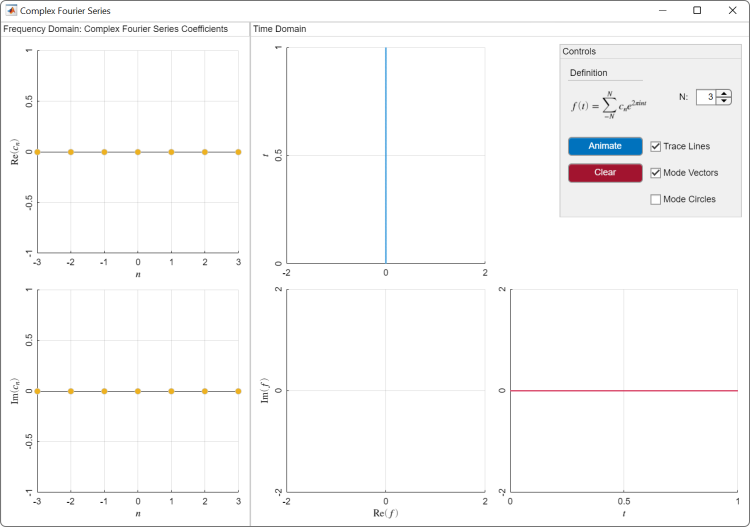](matlab: run ComplexFourierSeries)

[ComplexFourierSeries.mlapp](matlab: run ComplexFourierSeries)

**Tarea 2**. El dominio de frecuencia se muestra en el panel del lado izquierdo. Ajusta el coeficiente del segundo modo ($n=2$) de manera que $c_2=1$. Deja todos los demás $c_n=0$.

- Puedes ajustar los modos haciendo clic y arrastrando el tallo del coeficiente. 

- Solo necesitas ajustar la primera gráfica, que contiene las partes reales de los coeficientes.

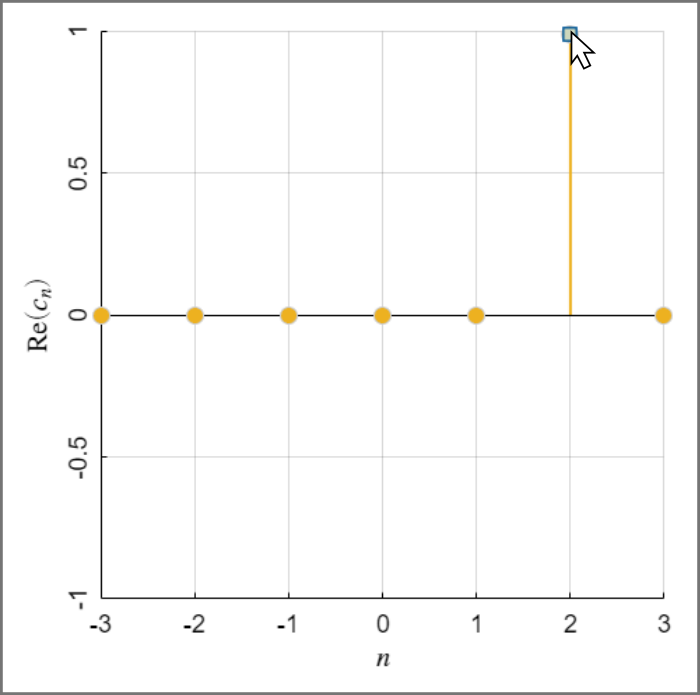

**Tarea 3.** Revisa el resultado mostrado en cada gráfica. Revisa las etiquetas de los ejes y las descripciones a continuación para identificar qué se muestra en cada gráfica.

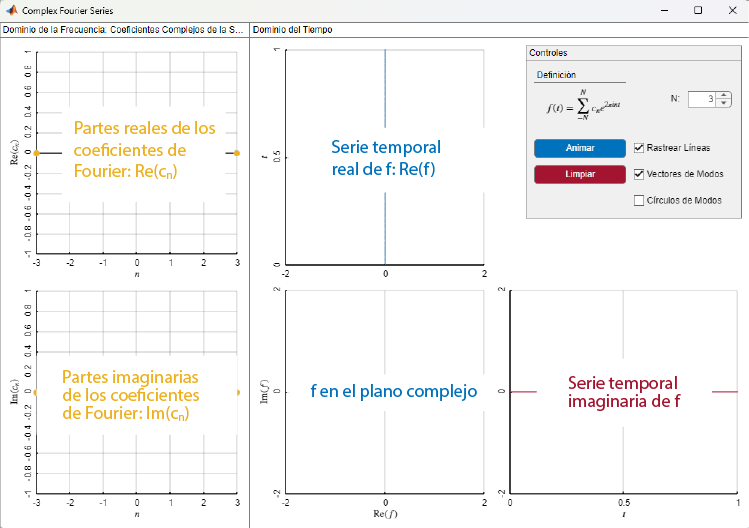

*Descripciones de las gráficas en la aplicación de la serie de Fourier compleja. Observa que en la serie temporal real, los ejes se han invertido para que la componente real coincida con el eje real del plano complejo.*

**Tarea 4.** Presiona el botón de **Animar** para animar el modo a lo largo del tiempo. Observa que el modo contiene tanto componentes reales como imaginarias.

**Tarea 5.** Presiona el botón de **Limpiar** para restablecer los coeficientes.

**Tarea 6**. Ajusta el coeficiente del primer modo de manera que $c_1=i$ (todos los demás $c_n=0$) y anima la gráfica.

- Utiliza la segunda gráfica ($\text{Im}(c_n)$) para ajustar la parte imaginaria del coeficiente del modo.

- Cuando cambiaste $c_1$ de $c_1=1$ a $c_1=i$, la gráfica compleja no cambió (todavía muestra un círculo unitario). Sin embargo, las series temporales han cambiado. ¿Cómo ha cambiado la serie temporal real?

**Tarea 7.** Limpia la aplicación. Luego, crea un modo con un coeficiente complejo: $c_1=1+i$. Debes ajustar tanto la parte real como la imaginaria del coeficiente a 1. 

- ¿Cómo cambia la gráfica compleja? 

- ¿Cómo cambian las series temporales real e imaginaria?

**Tarea 8.** Repite las tareas 2-7, pero utiliza un modo de frecuencia más alta: `n = 3`. Continúa observando solo un modo a la vez.

- ¿Cómo cambia la gráfica compleja en comparación con el caso donde $n=1$?

- ¿Cómo cambian las gráficas de las series temporales en comparación con el caso donde $n=1$?

En las **Tareas 2-4**, estableciste $c_1=1$ (mientras que todos los demás $c_n=0$). Esto significa que la serie de Fourier consistía en un solo modo:

$f(t) = 1 e^{2 \pi i  t}  =  \cos\left(2  \pi  t \right) + i \sin \left( 2 \pi  t \right)$.

Observa que la componente real de $f$ es una onda coseno pura de 1 Hz (observada en la serie temporal real), y la componente imaginaria es una onda seno pura de 1 Hz (observada en la serie temporal imaginaria).

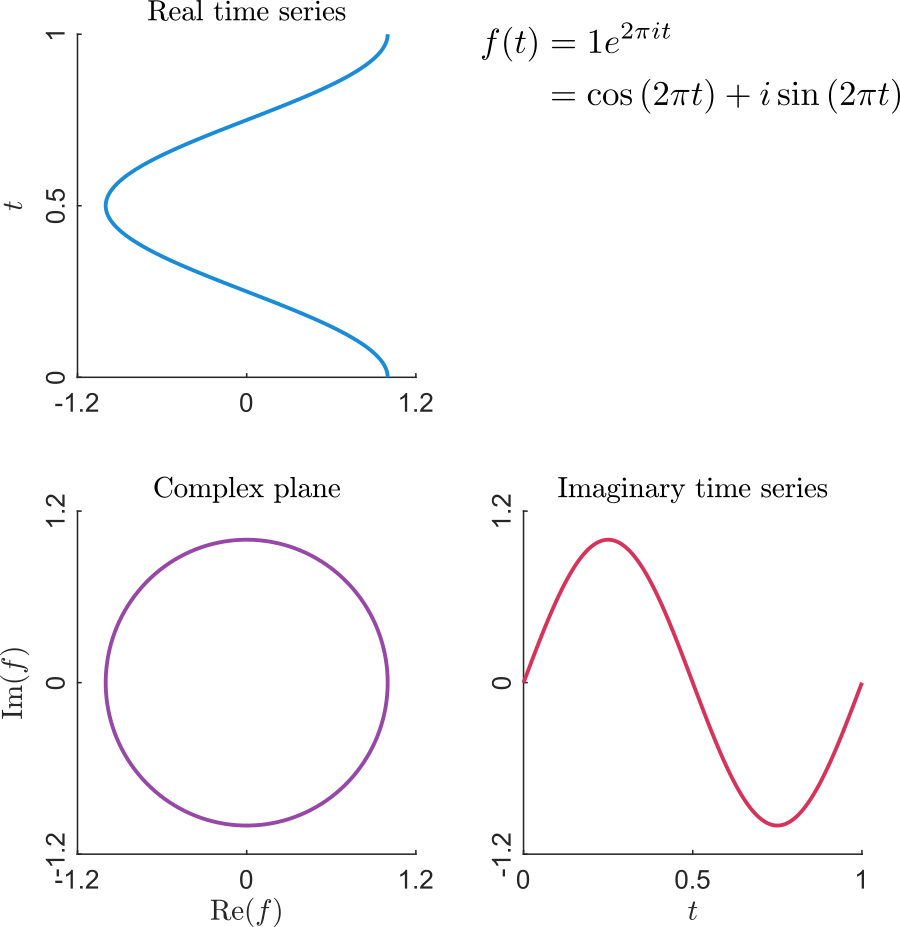

Gráficas en el dominio temporal de  con un solo modo, $c_1=1$.

** Ejercicio.** A mano, escribe la serie de Fourier con $c_1=i$ y todos los demás $c_n=0$.

- ¿Cuáles son las componentes real e imaginaria de la serie de Fourier, $f$?

- ¿Cómo se reflejan estas componentes en las gráficas de la serie temporal que observaste en la aplicación?

## Representando funciones reales con series complejas

En la actividad anterior, probablemente notaste que cada modo viene con una componente real y una imaginaria. De hecho, sin importar qué coeficiente complejo $c_n$ se seleccione (excepto 0), el modo siempre contendrá una combinación de partes reales e imaginarias.

Entonces, ¿cómo se crea una función de valor real a partir de estos modos? Por ejemplo, ¿qué coeficientes crearán una onda seno pura de 1 Hz?


$$y(t) = \sin( 2 \pi t)$$


La respuesta es combinar frecuencias positivas y negativas "de la manera correcta" para que las partes imaginarias "se cancelen".

### Modos reales a partir de complejos

  ** Actividad.** En esta actividad, crearás modos reales combinando modos complejos.

Tarea 1. Ejecuta la aplicación de la serie de Fourier compleja.

[](matlab: run ComplexFourierSeries)

[ComplexFourierSeries.mlapp](matlab: run ComplexFourierSeries)

**Tarea 2.** Establece el coeficiente de Fourier $c_1=0.5$. 

Tarea 3. Ajustando el coeficiente de Fourier con la misma frecuencia pero negativa ($c_{-1}$), puedes producir una señal real. Ajusta la parte real y/o imaginaria de $c_{-1}$ para producir una señal real.

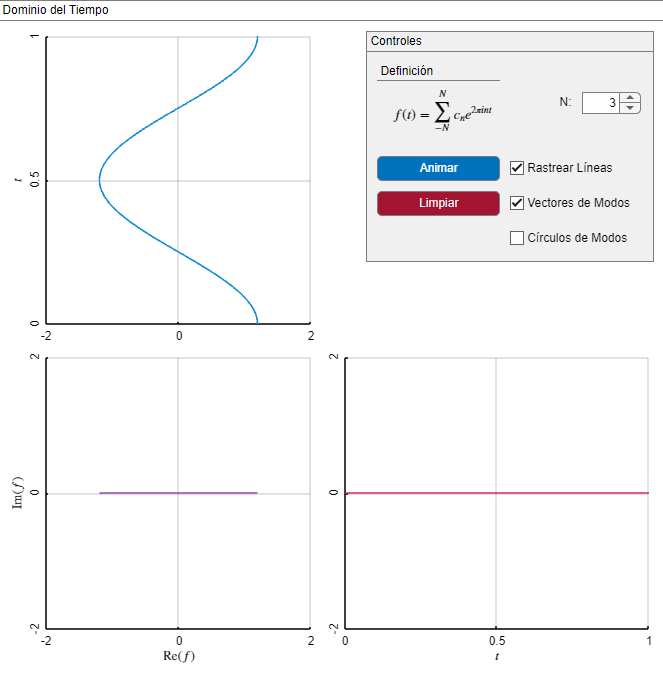

*Si es correcto, deberías encontrar que has creado una curva coseno real. La componente imaginaria debería ser cero.*

**Tarea 4.** A mano, escribe la serie de Fourier con los dos coeficientes que utilizaste en las **Tareas 2** y **3**. Utiliza la definición dada por la aplicación:


$$f(t) = \sum_{-N}^N c_n e^{ 2 \pi i n t}$$


Luego, simplifica el resultado expandiendo los exponenciales complejos utilizando la fórmula de Euler. Si es correcto, deberías encontrar


$$f(t) = \cos(2 \pi t)$$


**Tarea 5.** Anima la gráfica. Observa que ambos modos complejos existen pero se combinan "justo así" para "cancelar" la parte imaginaria.

- Visualiza la trayectoria circular de cada modo complejo seleccionando la casilla "Círculos de modo" y volviendo a ejecutar la animación.

- Observa que los dos círculos complejos tienen la misma frecuencia y magnitud pero se recorren en direcciones opuestas. Esto es el resultado de usar un componente de frecuencia negativa.

**Tarea 6.** En las **Tareas 2-4**, encontraste los coeficientes que producirían una onda coseno real de 1 Hz a partir de la transformada de Fourier compleja. Considera la expansión que hiciste en la **Tarea 4** con solo $c_1$ y $c_{-1}$:


$$f(t) = c_{-1} e^{ - 2 \pi i t} + c_{1} e^{ 2 \pi i t}$$


¿Puedes identificar coeficientes complejos $c_1$ y $c_{-1}$ que producirán una onda seno real de 1 Hz? Registra tu respuesta a continuación.

**Pista:** expande los exponenciales complejos utilizando la fórmula de Euler.

  **Consejo profesional.** Para escribir un número complejo, puedes utilizar la notación matemática estándar. Por ejemplo, $w=3+2i$ se puede escribir en MATLAB como 

% Reemplaza NaN con tus respuestas
cm1 = NaN; % c_{-1}
c1 = NaN; % c_1

**Tarea 7.** Verifica tu resultado estableciendo los coeficientes dentro de la aplicación con los valores que identificaste en la **Tarea 6**. Luego, anima la gráfica.

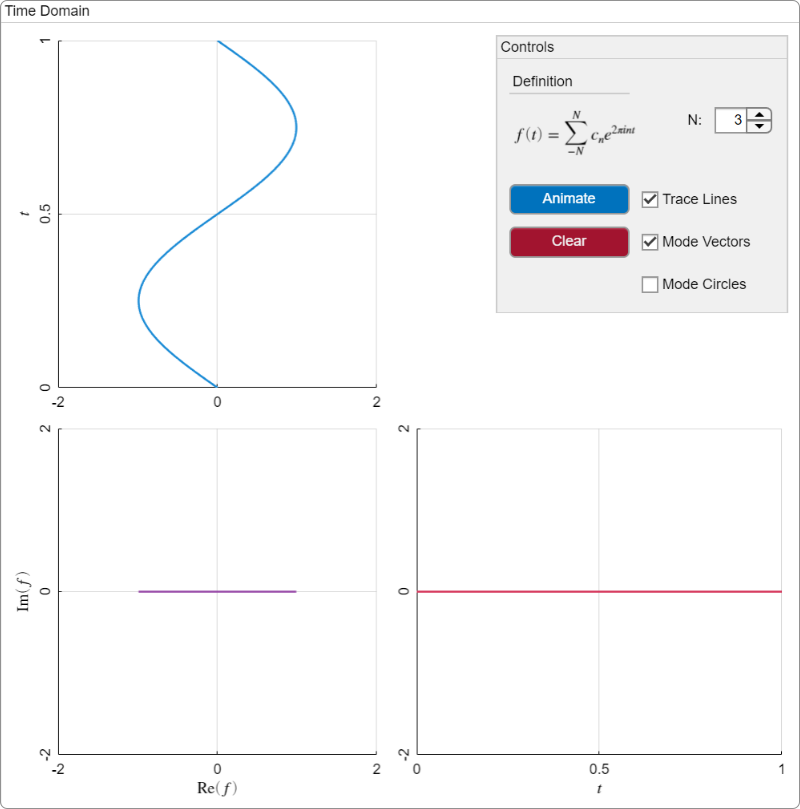

*Resultado correcto*

#### Relación entre las series reales y complejas

En general, para producir un modo real, el coeficiente de frecuencia negativa $c_{-n}$ debe ser el conjugado complejo del modo de frecuencia positiva correspondiente: $c_{-n} = {c_n}^*$. Recuerda que el conjugado complejo de $a+bi$ es $a-bi$. Puedes demostrar que esto es exactamente lo que se necesita para "cancelar" la componente imaginaria de la serie. Este hecho conduce a la relación entre las series de Fourier reales y complejas. Considera la serie de Fourier seno-coseno real:


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


La serie de Fourier compleja correspondiente es

$f(t) = \sum_{-\infty}^\infty c_n e^{ \frac{i n \pi}{L} t}$    con    $c_n = \frac{1}{2} \left\{
 \begin{array}{rl} 
a_0; & n = 0 \\ 
a_n - i b_n; & n > 0 \\ 
a_{-n} + i b_{-n}; & n < 0 \\ 
 \end{array}
 \right.$

 **Ejercicio.** Escribe la serie de Fourier compleja en términos de $a_n$ y $b_n$ mostrados arriba y aplica la fórmula de Euler. Verifica que el resultado sea equivalente a la serie de Fourier real.

### Combinación de modos

En la última actividad, combinaste modos complejos para crear senos y cosenos reales. Con esos bloques de construcción reales, puedes combinar muchas frecuencias para reproducir una función periódica, al igual que lo harías con una serie de Fourier real.

   **Actividad.** En esta actividad, combinarás varios modos complejos para crear una función real.

**Tarea 1.** Ejecuta la aplicación de la serie de Fourier compleja.

[](matlab: run ComplexFourierSeries)

[ComplexFourierSeries.mlapp](matlab: run ComplexFourierSeries)

Tarea 2. Establece los coeficientes de Fourier para generar la función real:


$$f(t) = \cos( 2 \pi t ) + \cos(6 \pi t )$$


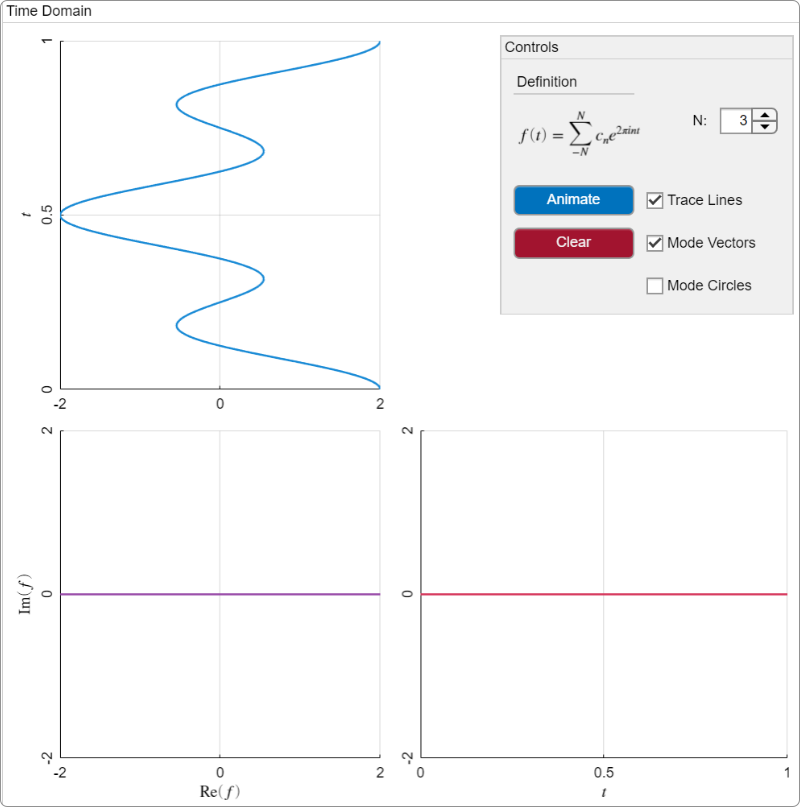

*Si es correcto, tu función debería aparecer como la suma de una onda seno de 1 Hz y 3 Hz.*

**Pista: C**rea las curvas coseno utilizando las frecuencias positivas primero. Luego, utiliza las frecuencias negativas para "cancelar" las componentes imaginarias.

**Tarea 3.** Anima la gráfica con (y sin) los círculos de modo dibujados. Observa que los modos de alta frecuencia giran más rápido que los modos de baja frecuencia, generando las oscilaciones de mayor frecuencia en la gráfica del dominio temporal.

**Tarea 4.** Repite las **Tareas 2** y **3** para la función de valor real


$$f(t) = 0.5 + \sin(2 \pi t) + \cos( 2 \pi t) - \sin( 4 \pi t)$$


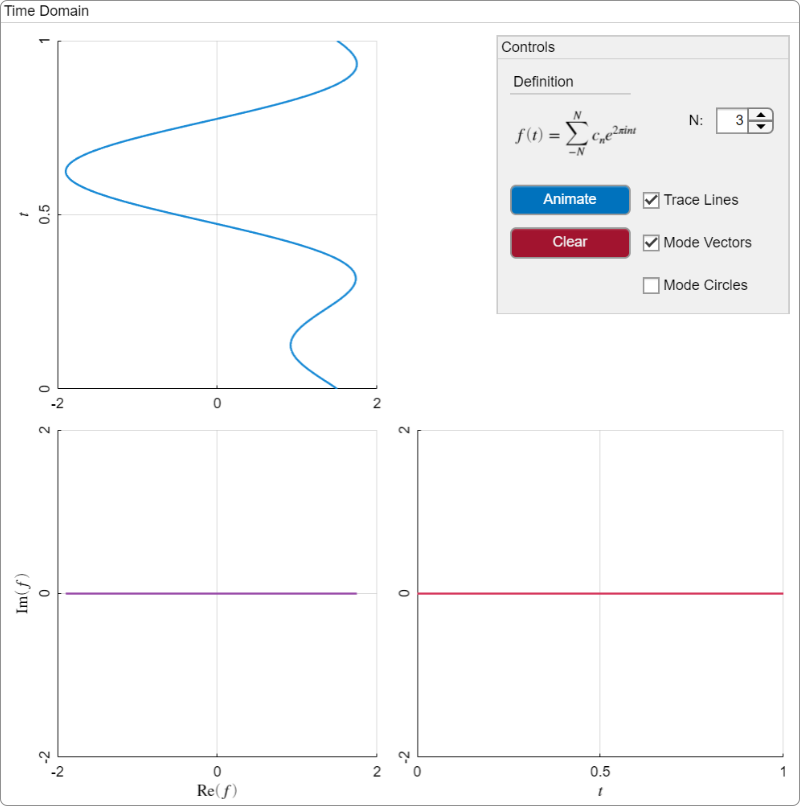

*Resultado correcto*

Ejercicio. Utiliza la fórmula de integración


$$c_n = \frac{1}{2L} \int_{-L}^{L} y(t) e^{ -\frac{i n \pi}{L} t} dt$$


con $L=0.5$ (para que coincida con la definición en la aplicación) para derivar los coeficientes de la serie compleja para la función 


$$f(t) = \cos( 2 \pi t ) + \cos(6 \pi t )$$


¿Coinciden con el resultado que encontraste en la actividad?

**Pista:** comienza por reescribir los senos y cosenos en términos de exponenciales complejas utilizando las fórmulas:

$\cos \theta = \frac{e^{i \theta} + e^{- i \theta}}{2}$    y    $\sin \theta = \frac{e^{i \theta} - e^{- i \theta}}{2i}$

La serie de Fourier compleja para una señal discreta se puede estimar utilizando una aproximación discreta para la integral en la fórmula de los coeficientes.

   ** Ejemplo.** Ejecuta esta sección para ver los coeficientes de la serie de Fourier compleja $c_n$ calculados para una nota de guitarra.

% Este código lee y reproduce el sonido de la guitarra
[yGuitar,FsGuitar] = audioread("Dnote.mp3");
soundsc(yGuitar,FsGuitar)
% Esta función auxiliar calcula los coeficientes de Fourier complejos
[freq,c] = computeGuitarComplexFourierCoef(yGuitar,FsGuitar);
plotComplexCoef(freq,c); % Genera la gráfica
 

 **Reflexionar.** 

- ¿Qué frecuencia es dominante?

- Observa que la gráfica se refleja (con pequeñas diferencias) alrededor de $n=0$. ¿Por qué?

- ¿Cuál es el significado/propósito de las frecuencias negativas?

### Magnitud y fase de la serie compleja

Si bien es importante comprender los coeficientes complejos $c_n$ en la forma estándar $(a+bi)$, los gráficos pueden resultar confusos. Al igual que con las series reales, puedes representar la fase y la magnitud de los coeficientes complejos para obtener una imagen más clara del dominio de la frecuencia. Para hacer esto, debes reescribir los coeficientes complejos en términos de fase y magnitud. Esto se puede hacer utilizando la forma polar de los números complejos:


$$a + bi = A e^{i \phi}$$


donde $A$ es la magnitud y $\phi$ es la fase. Esto a menudo se conoce como *forma polar*.

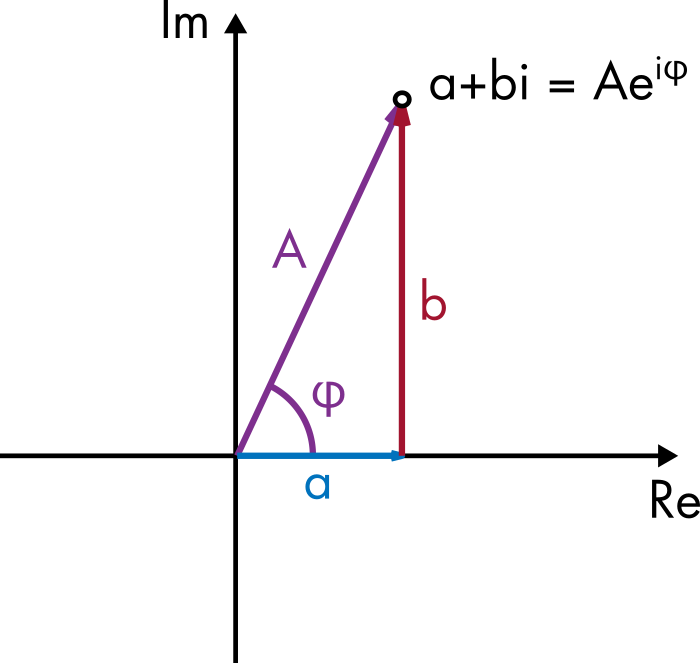

*La forma estándar y polar de un número complejo visualizado en el plano complejo*

La magnitud se puede calcular a partir de las componentes de $a+bi$ utilizando:


$$A=\sqrt{a^2+b^2}$$


La fase se puede calcular utilizando `atan2`:


$$\phi = \text{atan2}\left(b,a\right)$$


¿Te resulta familiar? Estas son exactamente las mismas fórmulas que se utilizan para calcular la magnitud y la fase a partir de los coeficientes de seno y coseno en una serie de Fourier real. Utilizando estas fórmulas, puedes calcular la magnitud y el desplazamiento de fase de cualquier modo complejo de la serie de Fourier directamente a partir del coeficiente $c_n$.

   **Actividad.** El código a continuación anima la gráfica de un único modo complejo de 2 Hz $f_2(t) = c_2e^{4\pi i t}$ con el coeficiente complejo en forma polar: $c_2=Ae^{i\phi}$.

- Cambia la magnitud del coeficiente $A$ y ejecuta la animación. ¿Cómo cambia el modo?

- Cambia la fase $\phi$ de $c_2$ y ejecuta la animación. ¿Cómo cambia el modo?

A = 1; % Magnitud del coeficiente complejo
phi =0; % Fase del coeficiente complejo
 
cn = A*exp(1i*phi)
omega = 2*2*pi; % frecuencia angular del modo en rad/s
traceSineCosine(A,omega,phi,3,true); % Función auxiliar que genera la gráfica

Después de calcular los coeficientes de Fourier complejos para una señal real, puedes calcular la fase y la magnitud para crear gráficas intuitivas del dominio de Fourier.

 **Ejercicio.** En esta sección, revisarás las gráficas de magnitud y fase de la nota de guitarra.

**Tarea 1.** Ejecuta esta sección para calcular los coeficientes de Fourier complejos. Los coeficientes complejos se almacenan en el vector `c`.

% Este código lee y reproduce el sonido de la guitarra
[yGuitar,FsGuitar] = audioread("Dnote.mp3");
soundsc(yGuitar,FsGuitar)
% Esta función auxiliar calcula los coeficientes de Fourier complejos
[freq,c] = computeGuitarComplexFourierCoef(yGuitar,FsGuitar);
 

**Tarea 2.** Calcula la magnitud y la fase de los coeficientes complejos, `c`. Puedes utilizar las fórmulas y estas funciones: [`real`](https://www.mathworks.com/help/matlab/ref/real.html), [`imag`](https://www.mathworks.com/help/matlab/ref/imag.html), [`atan2`](https://www.mathworks.com/help/matlab/ref/atan2.html), y [`sqrt`](https://www.mathworks.com/help/matlab/ref/sqrt.html), o utilizar las funciones [`abs`](https://www.mathworks.com/help/matlab/ref/abs.html) y [`angle`](https://www.mathworks.com/help/matlab/ref/angle.html).

% Calcula la magnitud y la fase
A = NaN;
phi = NaN;

**Tarea 3.** Crea un gráfico de tallo de la magnitud `A` en función de `freq`. Utiliza la función [`stem`](https://www.mathworks.com/help/matlab/ref/stem.html). Establece los límites de frecuencia en `[-800,800]` utilizando la función [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html).

figure % Crea una nueva figura
% Crea tu gráfico de tallo aquí



Observa que las magnitudes de las frecuencias negativas son iguales a las de las frecuencias positivas reflejadas. Esto siempre será cierto para una señal real, ya que los coeficientes de frecuencia negativa son los conjugados complejos de los coeficientes positivos: $c_{-n} = {c_n}^*$.

**Tarea 4.** Crea un gráfico de tallo de la fase `phi` que calculaste en la **Tarea 2**. Utiliza la función [`stem`](https://www.mathworks.com/help/matlab/ref/stem.html). Establece los límites de frecuencia en `[-800,800]` utilizando la función [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html).

figure % Crea una nueva figura
% Crea tu gráfico de tallo aquí



La mayoría de las fases no son relevantes para esta señal, ya que ocurren en frecuencias con magnitud despreciable.

**Tarea 5**. Identifica la fase de los dos picos de frecuencia más baja (en 146.6 y 294.4 Hz) en radianes. Comienza marcando las frecuencias correctas con líneas verticales utilizando [`xline`](https://www.mathworks.com/help/matlab/ref/xline.html). Por ejemplo, utiliza `xline(146.6)` para crear una línea vertical a través de 146.6 Hz.

Después de marcar las frecuencias, puedes hacer clic en los gráficos de tallo para crear un tooltip en la ubicación correcta y leer la fase desde allí.

% Agrega tus xlines aquí



**Pista:** Si te resulta difícil hacer clic en el punto correcto, abre la figura en una nueva ventana utilizando  y amplía el gráfico. También puedes hacer zoom en la región correcta utilizando la herramienta de zoom.

% Registra tus respuestas aquí
phase_147Hz = NaN; % En radianes
phase_294Hz = NaN; % En radianes

## Funciones de valor complejo

Las funciones de valor real son solo un caso especial de la serie de Fourier compleja más general. De hecho, la serie de Fourier compleja puede representar una amplia variedad de funciones complejas. Una función compleja tiene una componente real e imaginaria:


$$f(t) = f_{re}(t) + i f_{im}(t)$$


   **Actividad.** La lemniscata es una curva en forma de ocho que se puede describir con solo cuatro modos de la serie de Fourier compleja. En esta actividad, dibujarás una lemniscata en la aplicación. La lemniscata se puede describir mediante la función de valor complejo


$$f(t) = \cos (2 \pi t) + \frac{i}{2} \sin (4 \pi t)$$


**Tarea 1.** Ejecuta la aplicación de la serie de Fourier compleja.

[](matlab: run ComplexFourierSeries)

[ComplexFourierSeries.mlapp](matlab: run ComplexFourierSeries)

**Tarea 2.** Los dos primeros modos de la lemniscata describen una curva de coseno real con una frecuencia de 1 Hz. Ajusta los coeficientes de Fourier para crear el gráfico del coseno real que se muestra a continuación.

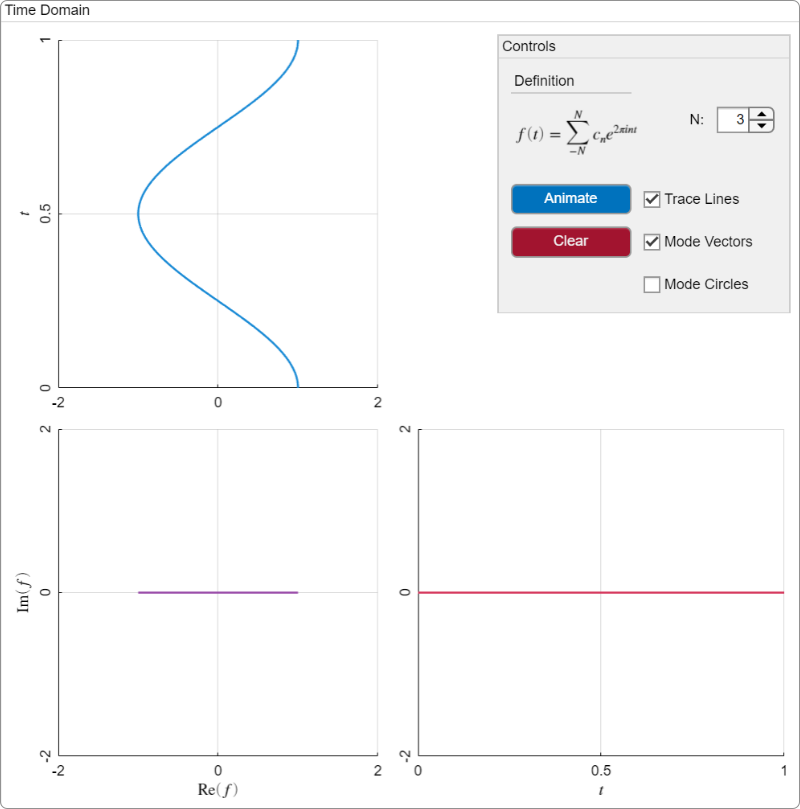

Tarea 3. Ajusta los coeficientes para el modo  para crear la componente imaginaria de la función: $ \frac{i}{2} \sin (4 \pi t)$. Si es correcto, la gráfica compleja debería mostrar la lemniscata.

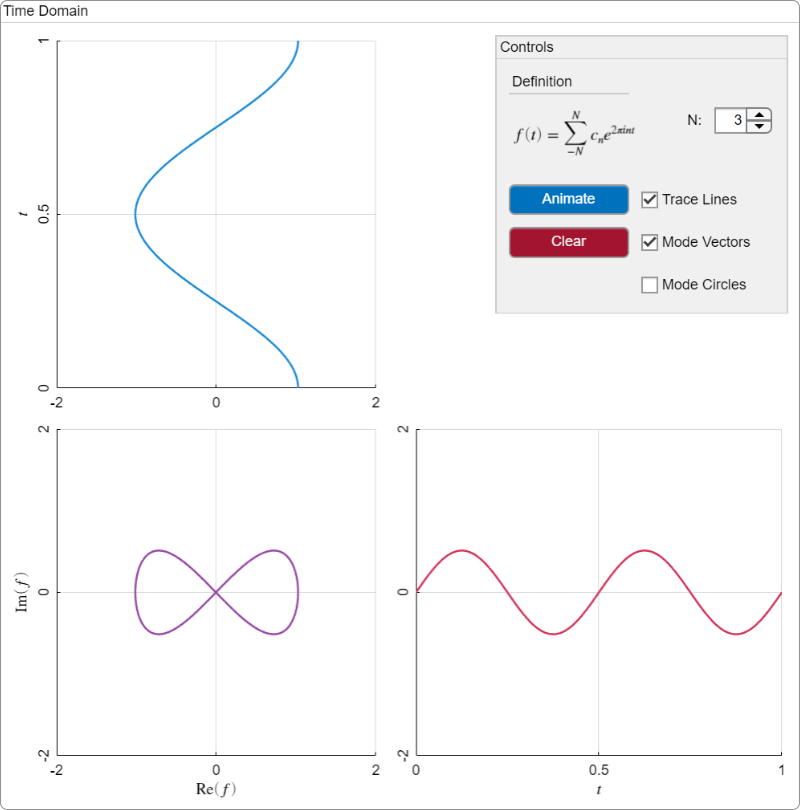

**Tarea 4.** Anima la gráfica.

** Ejercicio.** Utiliza la fórmula de integración


$$c_n = \frac{1}{2L} \int_{-L}^{L} y(t) e^{ -\frac{i n \pi}{L} t} dt$$


con $L=0.5$ (para que coincida con la definición en la aplicación) para derivar los coeficientes de la serie compleja para la función de la lemniscata:


$$f(t) = \cos (2 \pi t) + \frac{i}{2} \sin (4 \pi t)$$


¿Coinciden con el resultado que encontraste en la actividad?

**Pista:** Comienza por reescribir los senos y cosenos en términos de exponenciales complejas utilizando las fórmulas:

$\cos \theta = \frac{e^{i \theta} + e^{- i \theta}}{2}$    y    $\sin \theta = \frac{e^{i \theta} - e^{- i \theta}}{2i}$

[⇦ Descripción general del análisis de Fourier](matlab: OpenOverview)

**Funciones auxiliares**

function complexCircle(theta)
    % Esta función traza un círculo en el plano complejo
    % Con etiquetas para la fórmula de Euler
    
    f = exp(1i*theta * pi/180);
    thetaVec = 0:theta;
    fc = exp(1i*thetaVec*pi/180);
    
    colors = lines(7);
    
    figure
    quiver(0,0,real(f),imag(f),"off","LineWidth",1,"color",colors(4,:))
    hold on
    plot(real(fc),imag(fc),"LineWidth",1,"color",colors(4,:))
    quiver(0,0,real(f),0,"off","LineWidth",1,"color",colors(1,:))
    quiver(real(f),0,0,imag(f),"off","LineWidth",1,"color",colors(7,:))
    text(real(f)/2,0,"$\cos \theta$","Interpreter","latex",...
        "VerticalAlignment","top","HorizontalAlignment","center")
    text(real(f),imag(f)/2,"$\sin \theta$","Interpreter","latex",...
        "VerticalAlignment","middle","HorizontalAlignment","left")
    text(real(f)*1.1,imag(f)*1.1,"$e^{i \theta}$","Interpreter","latex",...
        "VerticalAlignment","middle","HorizontalAlignment","center")
    hold off
    
    axis equal
    axis(1.3*[-1 1 -1 1])
    xlabel("Re")
    ylabel("Im")
    title("Complex plane")
    xticks([-1,0,1])
    yticks([-1,0,1])
end

function [freq,c] = computeGuitarComplexFourierCoef(y,Fs)
    % Esta función estima los coeficientes complejos para la
    % transformada de Fourier compleja utilizando la regla del trapecio

    Nmodes = 1000;
    yc = y(1e4:5e4);
    
    tc = 1/Fs*(0:(length(yc)-1));
    L = tc(end)/2; % Se asume que el dominio es de 2L
    nvec = -Nmodes:Nmodes;
    freq = nvec/(2*L); % Frecuencias

    % Estimar los coeficientes utilizando la regla del trapecio
    c = zeros(1,numel(nvec));
    for k = nvec + Nmodes + 1
        c(k) = 1/(2*L)*trapz(tc,exp(-1i*nvec(k)*pi/L*tc).*yc);
    end
end


function pFig = figPos(ax,p)
    % Esta función calcula la posición de los puntos
    % en la figura

    axUnits = ax.Units;
    ax.Units = 'normalized';
    pos = ax.InnerPosition;

    % Desplazado para que el origen esté en la esquina inferior izquierda
    x = p(1)-ax.XLim(1);
    y = p(2)-ax.YLim(1);
    
    % Calcular la posición del punto en la figura
    xFig = x*(pos(3))/(ax.XLim(2) - ax.XLim(1)) + pos(1);
    yFig = y*(pos(4))/(ax.YLim(2) - ax.YLim(1)) + pos(2);
    
    pFig = [xFig,yFig];
    ax.Units = axUnits;
end

function traceSineCosine(mag,omega,phi,magLim,animateFlag)
    % Esta función genera la animación de un
    % solo modo de Fourier
    %
    % Mag: magnitud
    % Omega: frecuencia angular (rad/s)
    % Phi: desplazamiento de fase (rad)
    % magLim: límites del eje en términos de magnitud
    % animateFlag: si se anima o no

    freq = omega/(2*pi);

    % Esto define la función
    Nt = 150;
    tvec = linspace(0,1,Nt);
    fvec = mag*exp(freq*2*pi*1i*tvec + 1i*phi);
    
    % Configuraciones de apariencia
    timeColors = [     0    0.4470    0.7410;
        0.7350    0.1000    0.2500;
        0.4940    0.1840    0.5560]+0.1;
    
    imLims = magLim*[-1,1]; % Límites de Im en el plano complejo
    reLims = magLim*[-1,1]; % Límites de Re en el plano complejo       
    
    lwSeries = 1.25;
    lw = 0.75;

    % Configurar los ejes
    figure("position",[1,1,700,700])
    ax1 = subplot(2,2,3);
    ax2 = subplot(2,2,1);
    ax3 = subplot(2,2,4);
    
    % Gráficas
    reLine = plot(ax2,tvec*0,tvec,...
        "linewidth",lwSeries,"color",timeColors(1,:));
    imLine = plot(ax3,tvec,tvec*0,...
        "linewidth",lwSeries,"color",timeColors(2,:));     
    hold(ax1,"on")
    cmplxLine = plot(ax1,tvec*0,tvec*0,...
        "linewidth",lwSeries,"color",timeColors(3,:));
    arrow = quiver(ax1,0,0,0,0,"off","LineWidth",1,"color",timeColors(3,:));
    hold(ax1,"off")

    % Cambiar apariencia del gráfico: plano complejo
    set(ax1,"XLimMode","manual","YLimMode","manual")
    box(ax1,"off")
    xlim(ax1,reLims)
    ylim(ax1,imLims)
    xticks(ax1,[reLims(1), mean(reLims),reLims(2)])
    yticks(ax1,[imLims(1), mean(imLims),imLims(2)])
    xlabel(ax1,"Re$(f)$","interpreter","latex")
    ylabel(ax1,"Im$(f)$","interpreter","latex")
    title(ax1,"Complex plane","Interpreter","latex")
    ytickangle(ax1,90)
    
    % Cambiar apariencia del gráfico: real 
    box(ax2,"off")
    set(ax2,"XLimMode","manual","YLimMode","manual")
    xlim(ax2,reLims)
    ylim(ax2,[tvec(1),tvec(end)])
    xticks(ax2,[reLims(1), mean(reLims),reLims(2)])
    yticks(ax2,[tvec(1), mean(tvec),tvec(end)])
    ylabel(ax2,"$t$","interpreter","latex")
    title(ax2,"Real time series","Interpreter","latex")
    ytickangle(ax2,90)
    
    % Cambiar apariencia del gráfico: imaginaria
    box(ax3,"off")
    set(ax3,"XLimMode","manual","YLimMode","manual")
    ylim(ax3,imLims)
    xlim(ax3,[tvec(1),tvec(end)])
    yticks(ax3,[imLims(1), mean(imLims),imLims(2)])
    xticks(ax3,[tvec(1), mean(tvec),tvec(end)])
    xlabel(ax3,"$t$","interpreter","latex")
    title(ax3,"Imaginary time series","Interpreter","latex")
    ytickangle(ax3,90);
    
    crossLine1 = annotation("line",[0,0],[0,0],...
        "LineStyle","-","LineWidth",lw,"color",timeColors(1,:)+0.1);
    crossLine2 = annotation("line",[0,0],[0,0],...
        "LineStyle","-","LineWidth",lw,"color",timeColors(2,:)+0.1);
    
    kvec = 1:numel(tvec);
    if(~animateFlag)
        kvec = kvec(end);
        delete(crossLine1);
        delete(crossLine2);
    end

    for k = kvec
        t = tvec(k);
        f = fvec(k);
        
        % Este código crea las líneas de conexión
        pComplex = [real(f),imag(f)];
        pReal = [real(f),t];
        pImag = [t,imag(f)];
        
        pCFig = figPos(ax1,pComplex);
        pRFig = figPos(ax2,pReal);
        pIFig = figPos(ax3,pImag);
        
        % Actualizar las curvas
        cmplxLine.XData = real(fvec(1:k));
        cmplxLine.YData = imag(fvec(1:k));
        
        reLine.XData = real(fvec(1:k));
        reLine.YData = tvec(1:k);
        
        imLine.XData = tvec(1:k);
        imLine.YData = imag(fvec(1:k));
        
        arrow.UData = real(fvec(k));
        arrow.VData = imag(fvec(k));
        
        % Crear anotaciones entre los ejes
        p1 = [real(f),imag(f)];
        p2 = [real(f),t];
        p3 = [t,imag(f)];
        
        p1Fig = figPos(ax1,p1);
        p2Fig = figPos(ax2,p2);
        p3Fig = figPos(ax3,p3);
        
        if(animateFlag)
            crossLine1.X = [p1Fig(1),p2Fig(1)];
            crossLine1.Y = [p1Fig(2),p2Fig(2)];
            
            crossLine2.X = [p1Fig(1),p3Fig(1)];
            crossLine2.Y = [p1Fig(2),p3Fig(2)];
        end

    
        drawnow
    end
end

function plotComplexCoef(freq, c)
    % Crea una gráfica de las partes real e imaginaria
    % de los coeficientes complejos
    figure("position",[1,1,900,325])
    stem(freq,real(c),"Filled")
    hold on
    stem(freq,imag(c),"Filled")
    hold off
    xlabel("Frequency (Hz)")
    ylabel("Coefficient value")
    legend("Re(c_n)","Im(c_n)")
    title("Frequency domain")
    xlim([-800,800])
end